clc;
clear;
close all;


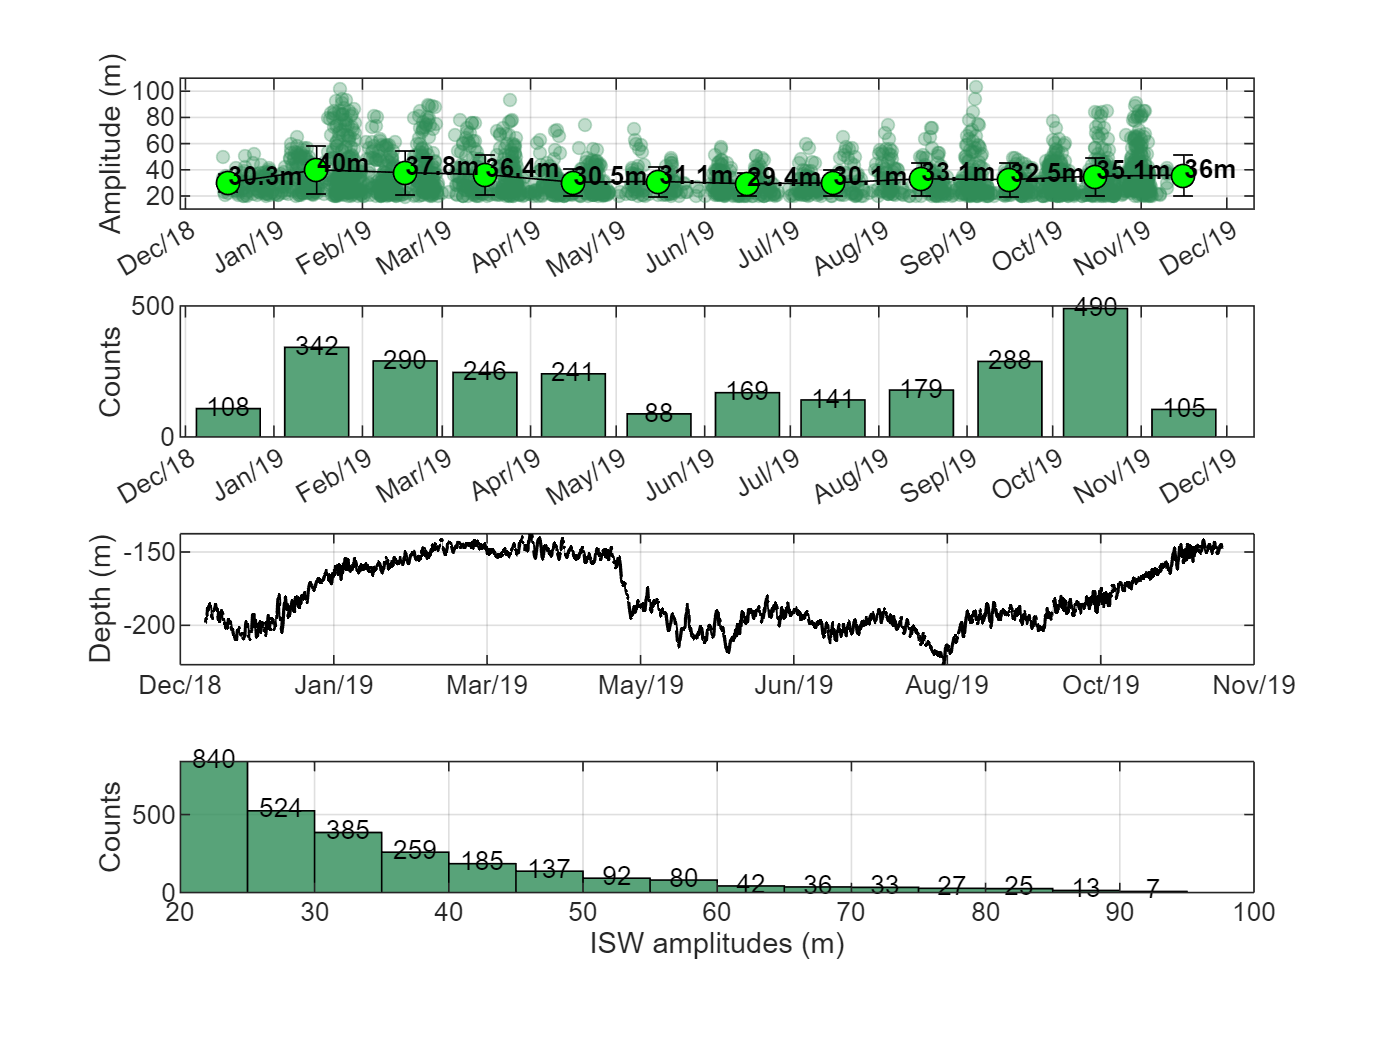

load("data_14.mat")

figure(11)
subplot(4,1,1)

scatter(isw_time_ind,iswamp,15,'markerfacecolor',[0.18 0.55 0.34],'markeredgecolor',[0.18 0.55 0.34]...
    ,'MarkerFaceAlpha',0.3,'MarkerEdgeAlpha',0.3)
hold on
errorbar(monthlyDatenums+15,avgamp,stdamp,'o','Color','k')
ylabel('Amplitude (m)')
hold on;grid on;box on;
plot(monthlyDatenums+15,avgamp,'k-o','MarkerFaceColor','g','MarkerSize',7)
for ii = 1:24
    text(monthlyDatenums(ii)+15,avgamp(ii)+5,[num2str(round(avgamp(ii),1)),'m'],...
        'FontSize',8,'FontWeight','bold')
end
xticks(monthlyDatenums); 
datetick('x','mmm/yy', 'keepticks')
xlim([dt(1)-15 dt(end)+30])
grid on
ylim([10,110])
% axis tight

subplot(4,1,2)
bar(monthlyDatenums+15,ampnum,'facecolor',[0.18 0.55 0.34],'FaceAlpha',0.8)
xticks(monthlyDatenums); 
datetick('x','mmm/yy', 'keepticks')
grid on;

xlim([dt(1)-15 dt(end)+30])

ylabel('Counts')
grid on

for ii = 1:length(ampnum)
    if ampnum(ii)>0
        text(monthlyDatenums(ii)+15, ampnum(ii)+5, num2str(ampnum(ii)), ...
            'HorizontalAlignment', 'center', 'FontSize', 8);
    end
end
hold on

subplot(4,1,3)
dt_x = interp1(1:476799,dt,x);
plot(dt_x,smoothed_y,'LineWidth',1,'Color','k')
grid on
datetick('x','mmm/yy', 'keepticks')
ylabel('Depth (m)')

subplot(4,1,4)

edges = 20:5:100;
[N, ~] = histcounts(iswamp, edges); 
histogram(iswamp,edges,'FaceColor',[0.18 0.55 0.34],'FaceAlpha',0.8)
grid on
axis tight;
xlabel('ISW amplitudes (m)')
ylabel('Counts')

binCenters = (edges(1:end-1) + edges(2:end)) / 2; 
for ii = 1:length(N)
    if N(ii) > 0 
        text(binCenters(ii), N(ii)+15, num2str(N(ii)), ...
            'HorizontalAlignment', 'center', 'FontSize', 8);
    end
end